% read an input 

train1_1 = imread('train_images/Set1/1.jpg');
train1_2 = imread('train_images/Set1/2.jpg');
train1_3 = imread('train_images/Set1/3.jpg');


## set 2


train2_1 = imread('train_images/Set2/1.jpg');
train2_2 = imread('train_images/Set2/2.jpg');
train2_3 = imread('train_images/Set2/3.jpg');


## To Grayscale

train1_1 = rgb2gray(train1_1);
train1_2 = rgb2gray(train1_2);
train1_3 = rgb2gray(train1_3);


## set 2

train2_1 = rgb2gray(train2_1);
train2_2 = rgb2gray(train2_2);
train2_3 = rgb2gray(train2_3);

## Corner Detection

cm2_1 = cornermetric(train2_1);
cm2_2 = cornermetric(train2_2);
cm2_3 = cornermetric(train2_3);


## ANMS Test

Nbest = 200;

lm1_1 = imregionalmax(cm1_1);


[x,y] = find(lm1_1);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm1_1(x(j),y(j)) > cm1_1(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');


## Test function


a = [2 4 6 8 10]
b = find(a > 3)

## ANMS Step

Nbest = 200;
c_best_1_1 = ANMS(cm1_1,Nbest);
c_best_1_2 = ANMS(cm1_2,Nbest);
c_best_1_3 = ANMS(cm1_3,Nbest);


## set 2

Nbest = 200;
c_best_2_1 = ANMS(cm2_1,Nbest);
c_best_2_2 = ANMS(cm2_2,Nbest);
c_best_2_3 = ANMS(cm2_3,Nbest);


## display


imshow(train1_1);
hold on;
scatter(c_best_1_1(2,:),c_best_1_1(1,:),'r.')
hold off;

imshow(train1_2);
hold on;
scatter(c_best_1_2(2,:),c_best_1_2(1,:),'r.')
hold off;

imshow(train1_3);
hold on;
scatter(c_best_1_3(2,:),c_best_1_3(1,:),'r.')
hold off;



## Feature Descriptor

H = fspecial('gaussian',40,0.5);

f_vector_1_1 = f_descriptor(c_best_1_1,train1_1,H);
f_vector_1_2 = f_descriptor(c_best_1_2,train1_2,H);
f_vector_1_3 = f_descriptor(c_best_1_3,train1_3,H);


## set 2



f_vector_2_1 = f_descriptor(c_best_2_1,train2_1,H);
f_vector_2_2 = f_descriptor(c_best_2_2,train2_2,H);
f_vector_2_3 = f_descriptor(c_best_2_3,train2_3,H);

## test


test1 = f_vector_1_1(:,7)
mean_1 = mean(test1)
var_1 = var(test1)


## Feature Matching

clear matchedpts1
clear matchedpts2
% ssd
index = 1;
mp_1_1_2 = zeros(2,size(c_best_1_2,2));
for i = 1:size(f_vector_1_1,2)
b_ssd = 1000000;
sb_ssd = 1000000;
    for j = 1:size(f_vector_1_2,2)
        ssd = 0;
        for k = 1:64 
            ssd = ssd + ((f_vector_1_1(k,i) - f_vector_1_2(k,j))^2); 
        end
        if ssd < b_ssd 
            sb_ssd = b_ssd;
            b_ssd = ssd;
            temp_1 = c_best_1_1(:,i);
            temp_2 = c_best_1_2(:,j);
                
        elseif ssd < sb_ssd 
            sb_ssd = ssd;
        end  
      
    end
    b_ssd/sb_ssd;
    if b_ssd/sb_ssd>0.95
    matchedpts1(:,index) =  temp_1;
    matchedpts2(:,index) =  temp_2;
    index = index+1;
    end
end
matchedpts1 = matchedpts1'
matchedpts2 = matchedpts2'



## Feature Matching from Deepti

clear matchedpts1
clear matchedpts2
k =1;
for i = 1:size(f_vector_1_1,2)
      first_pt = zeros(64,1);
      first = 1000000000000;
      second = 1000000000000;
    for j = 1:size(f_vector_1_2,2)
      dist = sum((f_vector_1_1(:,i) - f_vector_1_2(:,j)).^2);
        if dist <first
            second = first;
            first = dist;
            second_pt_index = j;
        elseif dist<second 
            second = dist;
        end
    end
    first/second;
    if first/second <0.7
        matchedpts1(k,:) = [c_best_1_1(2,i),c_best_1_1(1,i)];
        matchedpts2(k,:) = [c_best_1_2(2,second_pt_index),c_best_1_2(1,second_pt_index)];
        k = k+1;
    end    
end


## call feature matching

[matchedpts1,matchedpts2] = featurematching(f_vector_1_1, f_vector_1_2, c_best_1_1, c_best_1_2)
[matchedpts2_2,matchedpts3] = featurematching(f_vector_1_2, f_vector_1_3, c_best_1_2, c_best_1_3)


## set 2

[matchedpts2_1,matchedpts2_2] = featurematching(f_vector_2_1, f_vector_2_2, c_best_2_1, c_best_2_2)


## RANSAC

threshold = 10^2;
maxi = 30;
matchedpts1;
matchedpts2;
X = zeros(4,1);
Y = zeros(4,1);
x = zeros(4,1);
y = zeros(4,1);
percentage = 0;
% random no.
j=0;
while j <= 100 && percentage < 90
    for i = 1:4
        r = randi(size(matchedpts1,1));
        X(i,1) = matchedpts1(r,2);
        Y(i,1) = matchedpts1(r,1);
        x(i,1) = matchedpts2(r,2);
        y(i,1) = matchedpts2(r,1);
    end
    
    H = est_homography(x,y,X,Y);
    [X1, Y1] = apply_homography(H,matchedpts1(:,1), matchedpts1(:,2)) ;
    SSD(:,1) = matchedpts2(:,2) - X1 ;
    SSD(:,2) = matchedpts2(:,1) - Y1;
    SSD_n = SSD(:,1) + SSD(:,2);
    SSD_n = SSD_n.^2;
    if size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100 > percentage 
        percentage = size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100;
        inliers = find(SSD_n < threshold);
    end
    j = j + 1;
end
percentage
inliers;

inliers_1 = matchedpts1(inliers,:);
inliers_2 = matchedpts2(inliers,:);



H = est_homography(inliers_2(:,1),inliers_2(:,2),inliers_1(:,1),inliers_1(:,2))
[X1, Y1] = apply_homography(H,inliers_1(:,1), inliers_1(:,2));  
match_1 = [X1 Y1]
[X2, Y2] = apply_homography(H,inliers_2(:,1), inliers_2(:,2));  
match_2 = [X2 Y2] 


## call RANSAC

threshold = 10^2
%[inliers_1,inliers_2] = ransac(threshold,matchedpts1,matchedpts2)
[inliers_2_2,inliers_3] = ransac(threshold,matchedpts2_2,matchedpts3)


## set 2


threshold = 10^2
%[inliers_1,inliers_2] = ransac(threshold,matchedpts1,matchedpts2)
[inliers_2_1,inliers_2_2] = ransac(threshold,matchedpts2_1,matchedpts2_2)

## Image wrap 1 &2

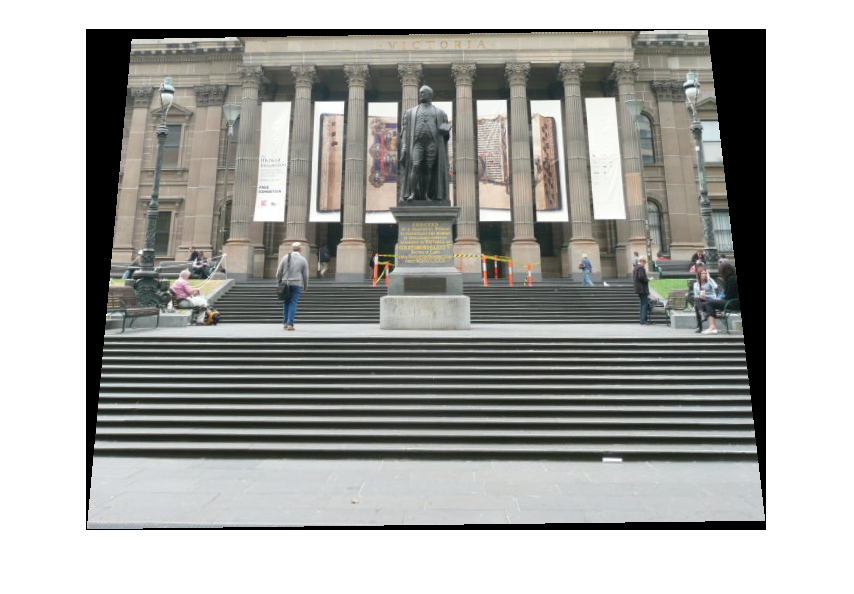

%output = imwarp(train1_2,tform_cpp )
% p = projective2d(H)
% output = imwarp(train1_1,p)
%imshow(output)

%imResult = blendMode_Average(train1_1, train1_2, 1, 1)
%imshow(imResult)

% Estimate the transformation between I(n) and I(n-1).
tforms(1) = projective2d(eye(3));
tforms(2) = estimateGeometricTransform(inliers_2,inliers_1,'projective', 'Confidence', 99.9, 'MaxNumTrials', 2000);
tforms(2).T = tforms(2).T*tforms(1).T;
output = imwarp(train1_2,tforms(2));
imshow(output)

## bleand


for i = 1:1        
    [xlim(i,:), ylim(i,:)] = outputLimits(tforms(i), [1 size(train1_1,1)], [1 size(train1_1,2)]);
end

xlim

xlim =      1   450


ylim

ylim =      1   600



maxImageSize = max(size(train1_1), size(train1_2))

maxImageSize =    450   600     3



% Find the minimum and maximum output limits 
xMin = min([1; xlim(:)]);
xMax = max([maxImageSize(2); xlim(:)]);

yMin = min([1; ylim(:)]);
yMax = max([maxImageSize(1); ylim(:)]);

% Width and height of panorama.
width  = round(xMax - xMin);
height = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([height width 3], 'like', train1_2);




blender = vision.AlphaBlender('Operation', 'Binary mask', 'MaskSource','Input port')

blender =   vision.AlphaBlender with properties:

         Operation: 'Binary mask'
        MaskSource: 'Input port'
    LocationSource: 'Property'
          Location: [1 1]



% Create a 2-D spatial reference object defining the size of the panorama.
xLimits = [xMin xMax];
yLimits = [yMin yMax];
panoramaView = imref2d([height width], double(xLimits), double(yLimits));


## Create the panorama.

sourceimage = imageDatastore({'train_images/Set1/1.jpg','train_images/Set1/2.jpg','train_images/Set1/3.jpg'})

sourceimage =   ImageDatastore with properties:

                       Files: {
                              ' ...\wwong\Desktop\HW\Computer Vision\Project 2\train_images\Set1\1.jpg';
                              ' ...\wwong\Desktop\HW\Computer Vision\Project 2\train_images\Set1\2.jpg';
                              ' ...\wwong\Desktop\HW\Computer Vision\Project 2\train_images\Set1\3.jpg'
                              }
    AlternateFileSystemRoots: {}
                    ReadSize: 1
                      Labels: {}
                     ReadFcn: @readDatastoreImage


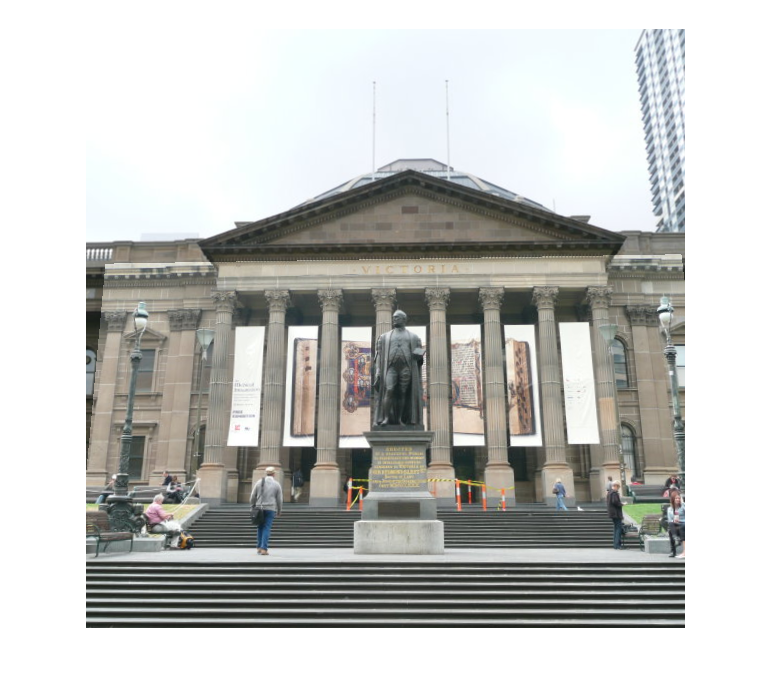


for i = 1:2 %numImages
    
    I = readimage(sourceimage, i);   
   
    % Transform I into the panorama.
    warpedImage = imwarp(I, tforms(i), 'OutputView', panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(I,1),size(I,2)), tforms(i), 'OutputView', panoramaView);
    
    % Overlay the warpedImage onto the panorama.
    panorama = step(blender, panorama, warpedImage, mask);
end

figure
imshow(panorama)

## for 2&3

tforms(2) = tforms(1)*estimateGeometricTransform(inliers_3,inliers_2,'projective', 'Confidence', 99.9, 'MaxNumTrials', 2000);
    output = imwarp(train1_2,tforms(2))
    imshow(output)
    

## Show

figure; ax = axes;
showMatchedFeatures(train1_1,train1_2,matchedpts1,matchedpts2,'montage','Parent',ax);
title(ax, 'Candidate point matches');
legend(ax, 'Matched points 1','Matched points 2');


## 2 & 3

figure; ax = axes;
showMatchedFeatures(train1_2,train1_3,matchedpts2_2,matchedpts3,'montage','Parent',ax);
title(ax, 'Candidate point matches');
legend(ax, 'Matched points 1','Matched points 2');

figure; ax = axes;
showMatchedFeatures(train1_2,train1_3,inliers_2_2,inliers_3,'montage','Parent',ax);
title(ax, 'RANSAC');
legend(ax, 'Matched points 1','Matched points 2');


## set 2

figure; ax = axes;
showMatchedFeatures(train2_1,train2_2,matchedpts2_1,matchedpts2_2,'montage','Parent',ax);
title(ax, 'Candidate point matches');
legend(ax, 'Matched points 1','Matched points 2');

figure; ax = axes;
showMatchedFeatures(train2_1,train2_2,inliers_2_1,inliers_2_2,'montage','Parent',ax);
title(ax, 'RANSAC');
legend(ax, 'Matched points 1','Matched points 2');



## Show 2

figure; ax = axes;
showMatchedFeatures(train1_1,train1_2,inliers_1,inliers_2,'montage','Parent',ax);
title(ax, 'RANSAC');
legend(ax, 'Matched points 1','Matched points 2');


## Function

function c_best = ANMS(cm,Nbest)

lm = imregionalmax(cm);


[x,y] = find(lm);

N_Strong = size(x,1);

r = inf(1,N_Strong);
ED = 0;

for i = 1:N_Strong
    for j = 1:N_Strong
        if cm(x(j),y(j)) > cm(x(i),y(i))
           ED =  (x(j)-x(i))^2 + (y(j)-y(i))^2;
           if ED < r(i)
              r(i) = ED;
           end 
        end
    end
end    

[sort_r,index] = sort(r,'descend');
c_best = zeros(2,Nbest);

for i = 1:Nbest
    c_best(1,i) = x(index(i)); 
    c_best(2,i) = y(index(i));
end
end

function f_vector = f_descriptor(cbest,I,H)
f_vector = zeros(64,size(cbest,2));
for i = 1:size(cbest,2)
    minx = max(1,cbest(1,i)-20);
    maxx = min(size(I,1),cbest(1,i)+19);
    miny = max(1,cbest(2,i)-20);
    maxy = min(size(I,2),cbest(2,i)+19);
    im_40 = I(minx:maxx,miny:maxy);
    b_40 = imfilter(im_40,H,'replicate');
    b_8 = imresize(b_40,[8 8]);
    f_vector(:,i) = b_8(:);
    f_vector(:,i) = f_vector(:,i) - ones(64,1)*mean(f_vector(:,i));
    f_vector(:,i) = f_vector(:,i)/std(f_vector(:,i));
end
end

function imResult = blendMode_Average(A, B, offsetW, offsetH)
%% Average blending mode: This blend mode simply adds pixel values of one  
%   layer with the other. In case of values above 1 (in the case of RGB),  
%   white is displayed. 
% 
% Input:
%       A       -       Base Image
%       B       -       Top Image
%   offsetW     -   move picture B horizontally in respect to the top-left
%                   corner of picture A. Default value = 1.
%   offsetH     -   move picture B vertically in respect to the top-left
%                   corner of picture A. Default value = 1.
%
% Output:
%       imResult    -   Result of the blending, having the same size of the
%                       Base Image A.
% 
%% Check Input
a = size(A);
b = size(B);
blendMode_checkInput(nargin, a, b, func2str(@blendMode_Average));
if nargin < 3
    offsetW = 1;
    offsetH = 1;
end
if nargin < 4
    offsetH = 1;
end
%% Implementation
imResult = A;
if (((offsetW ~= 1) || (offsetH ~= 1)) || (sum(a == b) ~= length(a)))
    [A, B] = blendMode_ResizeImages(A, B, a, b, offsetW, offsetH);
end
C = (A + B) / 2;
if (((offsetW ~= 1) || (offsetH ~= 1)) || (sum(a == b) ~= length(a)))
    imResult = blendMode_CreateResult(imResult, C, offsetW, offsetH);
else
    imResult = C;
end
end

function blendMode_checkInput(nargin, a, b, functionName)
%% Check input
if nargin < 2
    error(strcat(functionName, ':argChk'), 'Wrong number of input arguments.');
end
if ((length(a) ~= length(b)) || (a(end) ~= b(end)))
    error(strcat(functionName, ':argChk'), 'The number of dimensions of A must be equal to the number of dimension of B.');
end
end
% if nargin < 3
%     offsetW = 1;
%     offsetH = 1;
% end
% 
% if nargin < 4
%     offsetH = 1;
% end

function imResult = blendMode_CreateResult(imResult, C, offsetW, offsetH)
%% Combine the result of the blending to obtain the final image. This
%   function is used by every blend function.
% 
% Input:
%       A       -       Base Image
%       B       -       Top Image
%   offsetW     -   move picture B horizontally in respect to the top-left
%                   corner of picture A. Default value = 1.
%   offsetH     -   move picture B vertically in respect to the top-left
%                   corner of picture A. Default value = 1.
%
% Output:
%       imResult    -   Result of the blending, having the same size of the
%                       Base Image A.
% 
sW = offsetW;
eW = offsetW + size(C, 2) - 1;
sH = offsetH;
eH = offsetH + size(C, 1) - 1;
if offsetW < 1
    sW = 1;
    eW = size(C, 2);
end
if offsetH < 1
    sH = 1;
    eH = size(C, 1);
end
if ((sW <= eW) && (sH <= eH))
    imResult(sH : eH, sW : eW, :) = C;
end
end

function [m1,m2] = featurematching(f1,f2,c1,c2)
k =1;
for i = 1:size(f1,2)
      first_pt = zeros(64,1);
      first = 1000000000000;
      second = 1000000000000;
    for j = 1:size(f2,2)
      dist = sum((f1(:,i) - f2(:,j)).^2);
        if dist <first
            second = first;
            first = dist;
            second_pt_index = j;
        elseif dist<second 
            second = dist;
        end
    end
    if first/second <0.5
        m1(k,:) = [c1(2,i),c1(1,i)];
        m2(k,:) = [c2(2,second_pt_index),c2(1,second_pt_index)];
        k = k+1;
    end    
end
end

function [i1,i2] = ransac(t,m1,m2)
threshold =t ;
maxi = 100;
X = zeros(4,1);
Y = zeros(4,1);
x = zeros(4,1);
y = zeros(4,1);
percentage = 0;
j=0;



while j <= maxi && percentage < 90
    for i = 1:4
        r = randi(size(m1,1));
        X(i,1) = m1(r,2);
        Y(i,1) = m1(r,1);
        x(i,1) = m2(r,2);
        y(i,1) = m2(r,1);
    end
    
    H = est_homography(x,y,X,Y);
    [X1, Y1] = apply_homography(H,m1(:,1), m1(:,2)) ;
    SSD(:,1) = m2(:,2) - X1 ;
    SSD(:,2) = m2(:,1) - Y1;
    SSD_n = SSD(:,1) + SSD(:,2);
    SSD_n = SSD_n.^2;
    threshold = 10^floor(log10(mean(SSD_n))/2.5);
    if size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100 > percentage 
        best_ssd = SSD_n;
        percentage = size(SSD_n(SSD_n < threshold),1)/size(SSD_n,1)*100;
        inliers = find(SSD_n < threshold);
    end
    j = j + 1;
end
i1 = m1(inliers,:);
i2 = m2(inliers,:);
best_ssd
end



